# HW4

Question 4 is a bonus question. 

Questions 1 and 2 ask for computing some coefficients in frequency or time/sample domain. You can either type the values of these coefficients or make stem plots that show those values at each frequency or sample number. Note that plotting complex values includes separate magnitude and phase plots.

You may find the Matlab demo posted on Module 4 helpful.

Each question has 25 points.

## 1 

 Write a function X = dfs(x, N) to compute the Discrete Fourier Series (DFS) coefficients of a periodic 1-D signal, where: 

x is one period of the signal 

N is the fundamental period. 

Let x(n) = [0 1 2 3], N = 4. 

Find the DFS coefficients using your function.

function is called here but defined at the bottom.

x = [0, 1, 2, 3];
N = 4;
coeffs = dfs(x,N);
disp(coeffs)

   6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i



## 2 

Implement another function x = idfs(X, N) to compute the Inverse Discrete Fourier Series (IDFS), where :

X is the DFS coefficient array 

N is the fundamental period. 

Use the function idfs to retrieve back the original signal x(n) from the results of the previous part.

icoeffs = idfs(coeffs,N);
disp(real(icoeffs))

    0.0000    1.0000    2.0000    3.0000



## 3

The difference equation of a filter is given as $y\left(n\right)=-0\ldotp 8y\left(n-1\right)+0\ldotp 2x\left(n\right)$ 

Find its frequency response, 


$$y\left(n\right)=-0\ldotp 8y\left(n-1\right)+0\ldotp 2x\left(n\right)$$



$$y\left(n\right)+0\ldotp 8y\left(n-1\right)=0\ldotp 2x\left(n\right)$$



$$Y\left(z\right)+0\ldotp 8z^{-1} Y\left(z\right)=0\ldotp 2X\left(z\right)$$



$$Y\left(z\right)\left(1+\ldotp 8z^{-1} \right)=0\ldotp 2X\left(z\right)$$



$$\frac{Y\left(z\right)}{X\left(z\right)}=H\left(z\right)=\frac{\ldotp 2}{1+\ldotp 8z^{-1} }$$


evaluate at $z=e^{j\omega }$

plot the magnitude and phase responses, 

% Define the transfer function coefficients
b = 0.2;
a = [1, -0.8];  % Coefficients in the denominator (corrected)
k = 6.3

k = 6.3000

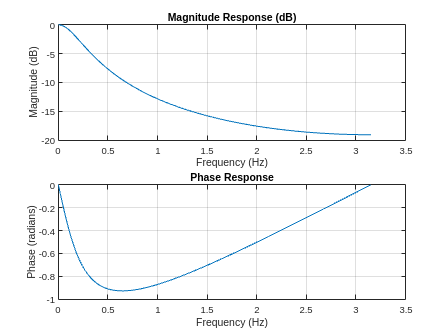

% Frequency vector
fs = k;  % Sampling frequency (you can adjust this)
num_points = 1024;  % Number of frequency points
frequencies = linspace(0, fs/2, num_points);  % Frequencies in the range [0, fs/2]

% Calculate the frequency responses at discrete frequencies on the unit circle
z = exp(1i * 2 * pi * frequencies / fs);  % Calculate z values
H = b ./ (1 +  a(2) * z.^(-1));  % Calculate H(z) for all frequencies (note the negative sign)

% Compute magnitude and phase responses
magnitude_response = abs(H);
phase_response = angle(H);

% Plot magnitude response in dB
subplot(2, 1, 1);
plot(frequencies,20*log10(magnitude_response));
title('Magnitude Response (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

% Plot phase response
subplot(2, 1, 2);
plot(frequencies, phase_response);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
grid on;

and state what type of a filter it is

It is a low pass filter. the magnitude drops opp as we increase the frequency. 

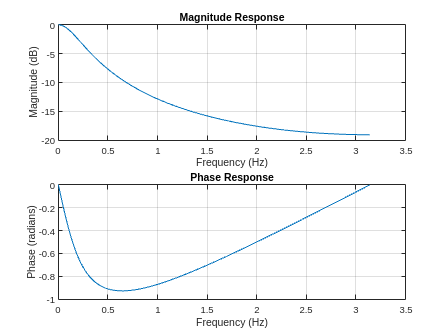

% testing my version against freqz
% Define the coefficients of the difference equation
a = [1, -0.8];  % Coefficients of y(n)
b = 0.2;        % Coefficient of x(n)

% Compute the transfer function
[H w] = freqz(b, a, 1024);  % Frequency response

% Calculate magnitude and phase responses
magnitude = abs(H);
phase = angle(H);

% Frequency vector
fs = 50;  % Sampling frequency (you can adjust this)
frequencies = (0:1023) * fs / 1024;

% Plot magnitude response
subplot(2,1,1);
plot(w, 20*log10(magnitude));
title('Magnitude Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
% Plot phase response
subplot(2,1,2);
plot(w, unwrap(phase));  % Unwrap phase for better visualization
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
grid on

% Define the transfer function coefficients
b = 0.2;
a = [1, -0.8];  % Coefficients in the denominator (corrected)
k = 25

k = 25

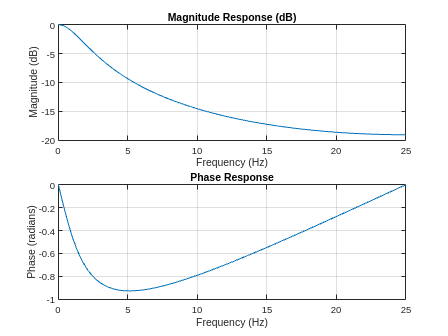

% Frequency vector
fs = 50;  % Sampling frequency (you can adjust this)
num_points = 1024;  % Number of frequency points
frequencies = linspace(0, k, num_points);  % Frequencies in the range [0, 1 Hz]

% Calculate the frequency responses at discrete frequencies on the unit circle
z = exp(1i * 2 * pi * frequencies / fs);  % Calculate z values
H = b ./ (1 +  a(2) * z.^(-1));  % Calculate H(z) for all frequencies (note the negative sign)

% Compute magnitude and phase responses
magnitude_response = abs(H);
phase_response = angle(H);

% Plot magnitude response in dB
subplot(2, 1, 1);
plot(frequencies,20*log10(magnitude_response));
title('Magnitude Response (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

% Plot phase response
subplot(2, 1, 2);
plot(frequencies, phase_response);
title('Phase Response');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
grid on;

## 4

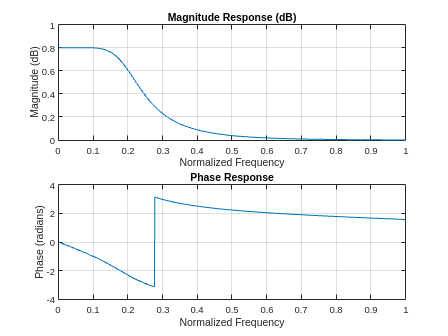

% Define the coefficients of the difference equation
b = [0.01, 0.05, 0.05, 0.01];  % Coefficients of x(n)
a = [1, -1.75, 1.18, -0.28];  % Coefficients of y(n)

% Frequency vector (normalized)
num_points = 1024;  % Number of frequency points
frequencies_normalized = linspace(0, 1, num_points);  % Frequencies in the range [0, 1]

% Calculate the frequency responses at discrete normalized frequencies
z = exp(-1i * 2 * pi * frequencies_normalized);  % Calculate z values with a negative exponent
H1 = freqz(b, a, 1024);  % Calculate H(z) for all frequencies

% Compute magnitude and phase responses
magnitude_response = abs(H1);
phase_response = angle(H1);

% Plot magnitude response in dB
subplot(2, 1, 1);
plot(frequencies_normalized, (magnitude_response));
title('Magnitude Response (dB)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot phase response
subplot(2, 1, 2);
plot(frequencies_normalized, phase_response);
title('Phase Response');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

function coeffs = dfs(x, N)    
% computes the Discrete Fourier Series (DFS) coefficients of a periodic 1-D signal
% x is one period of the signal 
% N is the fundamental period. 
fund_period = N;
signal = x;

% Ensure x and N have the same length
if length(signal) ~= N
    error('Length of x must be equal to N');
end

n = 0:fund_period-1;
k = 0:fund_period-1;

% Compute the DFS coefficients using vectorized operations
coeffs = signal * exp(-1i * 2 * pi * (n.') * k / fund_period);

end


function icoeffs = idfs(X, N)
% computes the Inverse Discrete Fourier Series coefficients of a periodic 1-D signal
% x is one period of the signal 
% N is the fundamental period. 
fund_period = N;
signal = X;
    % Ensure X and N have the same length
    if length(signal) ~= fund_period
        error('Length of X must be equal to N');
    end

    n = 0:fund_period-1;
    k = 0:fund_period-1;

    % Compute the IDFS
    icoeffs = (signal * exp(1i * 2 * pi * (n.') * k / fund_period)) / fund_period;

end
